# [增量式PID的matlab实现](https://www.cnblogs.com/qsyll0916/p/6890479.html) 

首先，增量式PID的实现公式：   **控制量增量**

式中 Δe(k)=e(k)-e(k-1)

进一步可以改写成

式中     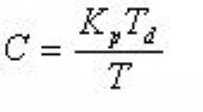

式中e（k）为第k次采样时的设定值与实际值的差，e（k-1）为上一次采样时的设定值与实际值的差值，e（k-2）一样类推。

所以增量式PID 输出的是控制量的增量，无积分作用，因此该方法适用于执行机构带积分部件的对象，如步进电机等，而位置式PID适用于执行机构不带积分部件的对象，如电液伺服阀。

**由于增量式PID输出的是控制量增量**，如果计算机出现故障，误动作影响较小，而执行机构本身有记忆功能，可仍保持原位，不会严重影响系统的工作，而位置式的输出直接对应对象的输出，

%执行机构需要的是控制量的增量，例如驱动不仅电机的时候，采用增量式PID控制，

%增量式PID控制算法中不需要累加，控制增量u(k)仅与最近k次的采样有关，所以误动作影响小。

%设一被控对象G（s）=50/(0.125s^2+7s),

%用增量式PID控制算法编写仿真程序

%（输入分别为单位阶跃、正弦信号，采样时间为1ms，控制器输出限幅：[-5,5],

%  仿真曲线包括系统输出及误差曲线，并加上注释、图例）。

# [**matlab**](https://so.csdn.net/so/search?q=matlab&spm=1001.2101.3001.7020)**编程思想**

离散的PID控制器，初始值输入值是0，在完整程序中，x=[0,0,0]'; %x(0) =(e(k)-e(k-1)); x(1)= e(k); x(2) = (e(k)-2*e(k-1)+e(k-2))。就想象着 x 轴的0点，PID输出的值经过被控系统产生的偏差再输入到PID中，经过一次一次的循环。最后达到稳定。

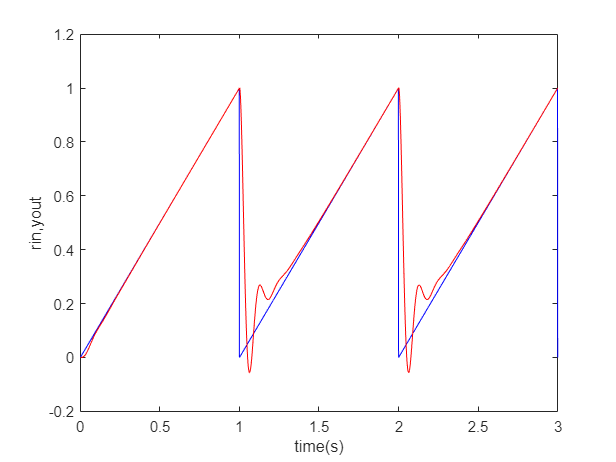

clc;
clear ;
ts=0.001;                  %采样时间
%sys=tf(50,[0.125,7, 0]);  %tf是传递函数，用来实现G（s）;  在自动控制领域经常用到，
sys=tf(400,[1,50,0]);
dsys=c2d(sys,ts,'z');        %把控制函数离散化，转化为拆分方程
[num,den]=tfdata(dsys,'v');  % 离散化后提取分子、分母 ，提取拆分方程系数
u_1=0.0;
u_2=0.0;
y_1=0.0;
y_2=0.0;
x=[0,0,0]';
error_1=0;
error_2=0;
for k=1:1:3000
    time(k)=k*ts;    %采样次数
    
    S=4;   %选择需要跟踪的函数
    if S==1
        % kp=10;ki=0.1;kd=15;             %初始化PID
        kp=8;ki=0.1;kd=10;
        rin(k)=1;            %Step Signal ，阶跃信号
    end

    if S==2
        kp=10;ki=0.1;kd=15;
        rin(k)=0.5*sin(2*pi*k*ts);       %Sine Signal   正弦信号
    end

    if S==3          %三角波信号
        kp=10;ki=0.1;kd=15;
        if mod(time(k),2)<1
            rin(k)=mod(time(k),1);
        else
            rin(k)=1-mod(time(k),1);
        end
        rin(k)=rin(k)-0.5;
    end

    if S==4     %锯齿波信号
        kp=8;ki=0.05;kd=4; %测试得合适参数，如果输出过冲，可将kd调小。
        rin(k)=mod(time(k),1);
    end
    
    du(k)=kp*x(1)+kd*x(2)+ki*x(3);      %PID Controller   控制系数
    u(k)=u_1+du(k);
    
    if u(k)>=10         %Restricting the output of controller，输出限幅
        u(k)=10;
    end
    if u(k)<=-10
        u(k)=-10;
    end
    
    %Linear model
    yout(k)=-den(2)*y_1-den(3)*y_2+num(2)*u_1+num(3)*u_2;          %实际输出
    error(k)=rin(k)-yout(k);                                       %Return of parameters 误差
    u_2=u_1;                                                       %保存上上次输入       为下次计算
    u_1=u(k);                                                      %保存上一次控制系数   为下次计算
    y_2=y_1;                                                       %保存上上次次输出     为下次计算
    y_1=yout(k);                                                   %保存上一次输出       为下次计算
    
    x(1)=error(k)-error_1;            %Calculating P
    x(2)=error(k)-2*error_1+error_2;  %Calculating D
    x(3)=error(k);                    %Calculating I
    
    error_2=error_1;
    error_1=error(k);
end

figure(1);
plot(time,rin,'b',time,yout,'r');                        %输入 和实际控制输出
xlabel('time(s)'),ylabel('rin,yout');

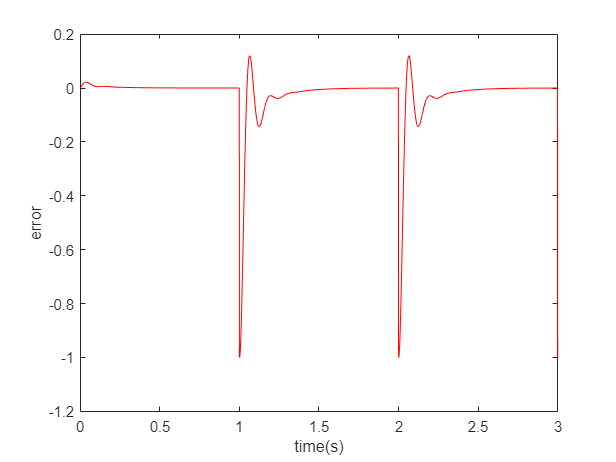

figure(2);
plot(time,error,'r')                                     %输入与输出误差输出曲线
xlabel('time(s)');ylabel('error');